% Load IEEE 9-bus system data
run('ieee9_A2.m');


%% part 1

% Number of buses - from the previous assignment
Y = admittance(nfrom, nto, r, x, b);

% Call the Newton-Raphson power flow function
[V, delta, Psl, Qgv, N, time] = nrpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('Converged in %d iterations and took %f seconds.\n', N, time);

Converged in 4 iterations and took 0.000096 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9856
    0.9962
    0.9576



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta);

         0
    0.1688
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl);

   71.9547



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv);

         0
   14.4601
   -3.6490
         0
         0
         0
         0
         0
         0





% Quick software validation: mismatches below toler at PQ/PV, and power balance
[Pf, Qf, Pt, Qt, Sfrom, Sto] = ac_line_flows(nfrom, nto, r, x, b, V, delta, Sbase);
Ploss = sum(Pf + Pt);
assert(Ploss > 0);  % positive losses
Pg_tot = sum(Pg) + Psl;
Pd_tot = sum(Pd);
assert(abs(Pg_tot - Pd_tot - Ploss) < 1e-3, 'Power balance check failed.');


%% part 2


% Call the Newton-Raphson power flow function
[V, delta, Psl, Qgv, N, time] = decpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('\nConverged in %d iterations and took %f seconds.\n', N, time);


Converged in 5 iterations and took 0.000110 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9857
    0.9962
    0.9576



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta);

         0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl);

   71.9545



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv);

         0
   14.4533
   -3.6550
         0
         0
         0
         0
         0
         0





%% part 3


% Call the Newton-Raphson power flow function
[V, delta, Psl, Qgv, N, time] = fastdecpf(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, toler, maxiter);

% Display the results
fprintf('\nConverged in %d iterations and took %f seconds.\n', N, time);


Converged in 5 iterations and took 0.000104 seconds.


disp('Voltage magnitudes (p.u.):');

Voltage magnitudes (p.u.):


disp(V);

    1.0000
    1.0000
    1.0000
    0.9870
    0.9755
    1.0034
    0.9857
    0.9962
    0.9577



disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta);

         0
    0.1687
    0.0833
   -0.0420
   -0.0701
    0.0336
    0.0108
    0.0663
   -0.0759



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl);

   71.9518



disp('Reactive power at PV buses (Mvar):');

Reactive power at PV buses (Mvar):


disp(Qgv);

         0
   14.4363
   -3.6614
         0
         0
         0
         0
         0
         0





%% part 4


% Call the Newton-Raphson power flow function
[delta, Psl, Pf] = dcpf(nfrom, nto, x, is, Pg, Pd, Sbase);

% Display the results
disp('Voltage angles (radians):');

Voltage angles (radians):


disp(delta);

         0
    0.1710
    0.0883
   -0.0386
   -0.0652
    0.0385
    0.0144
    0.0691
   -0.0709



disp('Active power at slack bus (MW):');

Active power at slack bus (MW):


disp(Psl);

    67



disp('Active power at transmission line (MW):');

Active power at transmission line (MW):


disp(Pf);

   67.0000
   28.9674
  -61.0326
   85.0000
   23.9674
  -76.0326
 -163.0000
   86.9674
  -38.0326




% 
% Q5 Compare AC vs DC active line flows
fprintf('\nLine  from-to    P_AC(MW)     |S|_from(MVA)   P_DC(MW)\n');


Line  from-to    P_AC(MW)     |S|_from(MVA)   P_DC(MW)


for e = 1:numel(nfrom)
    fprintf('%2d    %d  -> %d   %9.3f     %9.3f     %9.3f\n', e, nfrom(e), nto(e), Pf(e), Sfrom(e), Pf(e));
end

 1    1  -> 4      67.000        75.874        67.000
 2    4  -> 5      28.967        30.734        28.967
 3    5  -> 6     -61.033        61.643       -61.033
 4    3  -> 6      85.000        85.078        85.000
 5    6  -> 7      23.967        24.529        23.967
 6    7  -> 8     -76.033        76.725       -76.033
 7    8  -> 2    -163.000       163.016      -163.000
 8    8  -> 9      86.967        86.541        86.967
 9    9  -> 4     -38.033        54.346       -38.033



% === Q6 Feasibility (bus 7) ===


run('ieee9_A2.m');
% linspace(start, end, numPoints)
P7_vals = 0:20:400; Q7_vals = -400:20:400;
%P7_vals = linspace(0,400,30); Q7_vals=linspace(-200,200,30);
feas = pf_feasibility_map(Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, P7_vals, Q7_vals, toler, maxiter);

n = 9

feas = 21×41 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

fprintf('\nFeasibility map computed on %dx%d grid. Feasible points: %d\n', numel(P7_vals), numel(Q7_vals), nnz(feas));


Feasibility map computed on 21x41 grid. Feasible points: 108


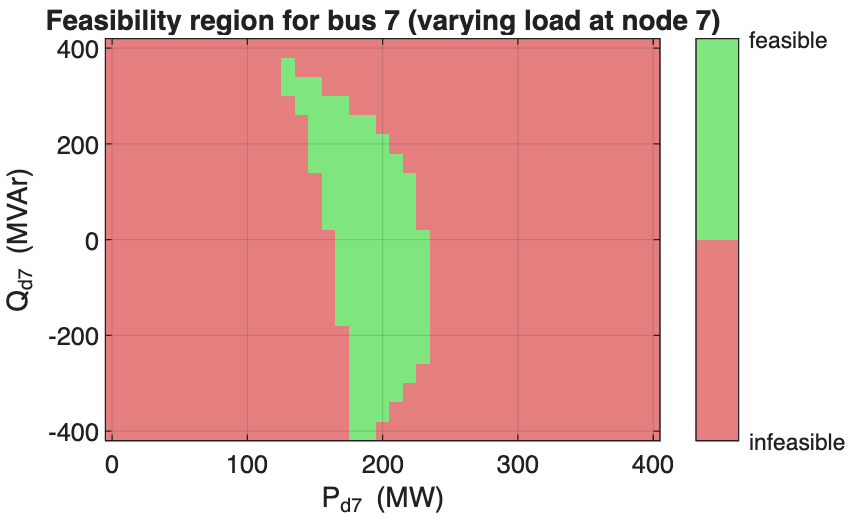



% Feasibility map for bus 7
figure; 
% If feas is sized [numel(Q7_vals) x numel(P7_vals)]:
imagesc(P7_vals, Q7_vals, double(feas));  % cast to double for color scaling
% If your loops filled feas as [numel(P7_vals) x numel(Q7_vals)], use:
% imagesc(P7_vals, Q7_vals, double(feas').');

set(gca,'YDir','normal'); axis tight
colormap([0.9 0.5 0.5; 0.5 0.9 0.5]);   % red-ish for infeasible, green-ish for feasible
% caxis([0 1]);
cb = colorbar('Ticks',[0 1],'TickLabels',{'infeasible','feasible'});
xlabel('P_{d7} (MW)'); ylabel('Q_{d7} (MVAr)');
title('Feasibility region for bus 7 (varying load at node 7)'); grid on


% hold on
% % Draw the 0–1 boundary as a contour at level 0.5:
% contour(P7_vals, Q7_vals, double(feas), [0.5 0.5], 'k', 'LineWidth', 1.5);
% hold off


% % Given: Y, is, Sbase, and your P7/Q7 grids
% P7_vals = linspace(0,400,30);
% Q7_vals = linspace(-200,200,30);
% V1mag   = 1.0;                        % sending-end magnitude (p.u.), e.g., slack spec
% 
% [feas, params] = pf_feasibility_map_eq31(Y, is, 7, Sbase, P7_vals, Q7_vals, V1mag);

run('ieee9_A2.m');

% Q7
% === Security analysis (N-1) ===
cont = [4 5; 4 9; 5 6; 6 7; 7 8; 8 9];
out = pf_security_analysis(nfrom, nto, r, x, b, Y, is, ipq, ipv, Pg, Qg, Pd, Qd, V0, Sbase, cont, toler, maxiter);
fprintf('\nN-1 contingencies (acceptable range 0.95–1.05 p.u.):\n');


N-1 contingencies (acceptable range 0.95–1.05 p.u.):


for k = 1:numel(out)
    fprintf('Outage %d-%d: Vmin=%.3f, Vmax=%.3f\n', out(k).pair(1), out(k).pair(2), out(k).Vmin, out(k).Vmax);
end

Outage 4-5: Vmin=0.908, Vmax=1.000
Outage 4-9: Vmin=0.794, Vmax=1.000
Outage 5-6: Vmin=0.919, Vmax=1.000
Outage 6-7: Vmin=0.946, Vmax=1.005
Outage 7-8: Vmin=0.933, Vmax=1.000
Outage 8-9: Vmin=0.890, Vmax=1.000
